# 11 The Fourier Transform, the Discrete Time Fourier Transform, the FFT, and the Convolution Theorem

The Fourier transform is an incredibly important signal-processing technique in time-series data analysis (like EEG) as well as in many other branches of science, engineering, and technology. In turn, the backbone of the Fourier transform is the dot product.

The Fourier transform works by computing the dot product between the signal (such as EEG data) and sine waves of different frequencies (the kernels). sine waves have three characteristics:

- Frequency

- Power

- Phase

Thus, the result of the Fourier transform is a three-dimensional (3-D) representation of the time series data in which the three dimensions are:

- Frequency

- Power

- Phase

This 3-D Fourier representation contains all of the information in the time series data, and the time series data can be perfectly reconstructed from the result of its Fourier transform.

## 11.1 Making Waves

Sine waves can be represented mathematically using the following formula:

### 
$$A\;\sin \left(2\pi \textrm{ft}+\theta \right)$$


- $A$ is the amplitude of the sine wave

- $\pi$ is pi, or 3.141 . . . 

- $f$ is the frequency of the sine wave

- $t$ is time

- $\theta$ is the phase angle offset, which is related to the value of the sine wave at $\textrm{time}=0$

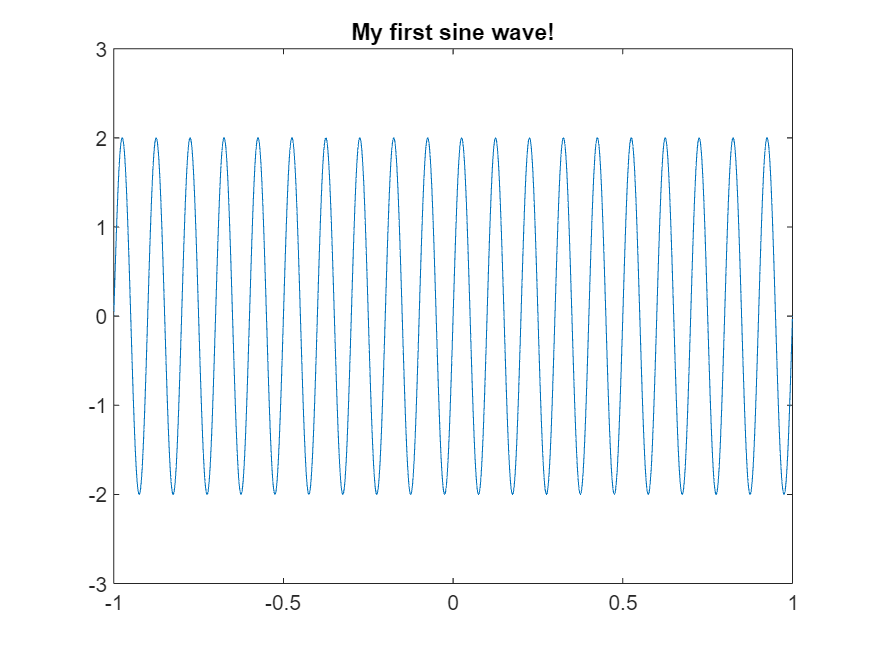

srate = 1000;
time  = -1:1/srate:1; 

freq  = 10;
amp   = 2;
phi   = 0;

sine_wave = amp.*sin(2*pi*freq.*time+phi);

figure
plot(time,sine_wave)
set(gca,'ylim',[-3 3])
title('My first sine wave!')

**Figure 11.1**

*A sine wave that was created using the expression *$\sin \left(2\pi 10t+0\right)$.

Sine waves can be better conceptualized as a spiral in a 3-D space and that what you see in 2D space is a projection onto two of the three dimensions. This gives the appearance of going up and down. 

By adding together several sine waves of different frequencies, amplitudes, and phases, the resulting time series looks more complicated than any of the individual sine waves.

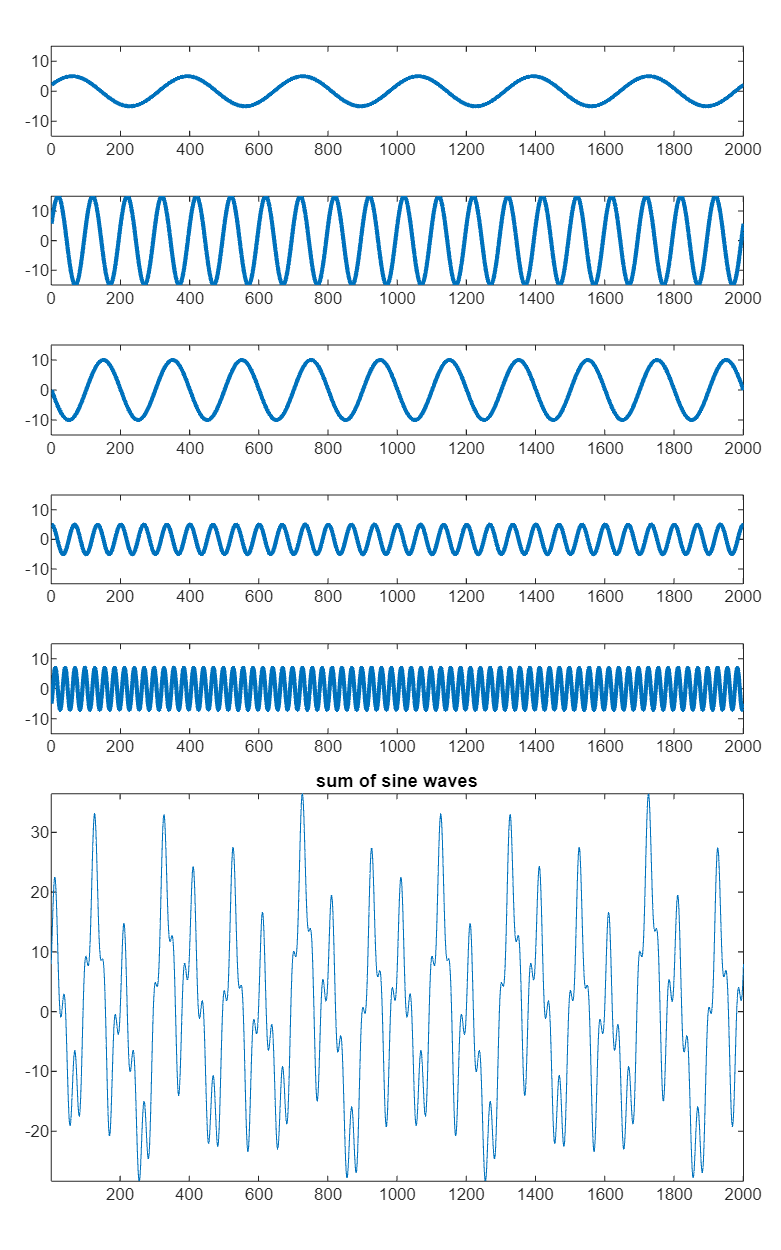

frex = [ 3   10   5   15   35 ];
amplit = [ 5   15   10   5   7 ];
phases = [  pi/7  pi/8  pi  pi/2  -pi/4 ];

sine_waves = zeros(length(frex),length(time));
for fi=1:length(frex)
    sine_waves(fi,:) = amplit(fi) * sin(2*pi*frex(fi).*time + phases(fi));
end

figure('Position', [100 100 500 800]);

num_rows = length(frex) + 3;
t = tiledlayout(num_rows, 1, 'TileSpacing', 'compact', 'Padding', 'compact');

for fi = 1:length(frex)
    nexttile;
    plot(sine_waves(fi,:), 'LineWidth', 2);
    axis([0 length(time) -max(amplit) max(amplit)]);
end

nexttile([3 1]); 
plot(sum(sine_waves));
axis tight;
title('sum of sine waves');

**Figure 11.2**

*Several sine waves of differing amplitudes, frequencies, and phases, plotted separately and afterbeing added together,*

Adding some noise makes the signal look more like real data:

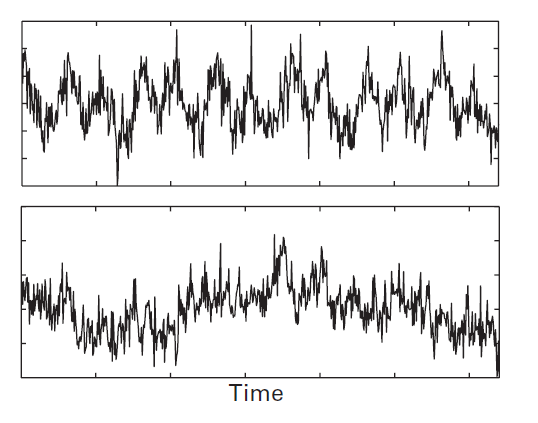

**Figure 11.3**

*One of these time series was generated by summing different sine waves and adding noise; the other time series is real EEG data. Can you guess which is which? What evidence do you use to support your decision?*

## 11.2 Finding Waves in EEG Data with the Fourier Transform

With real EEG data, you have the opposite problem compared with previous examples: you already have the time series, and you want to know which sine waves with which frequencies, amplitudes, and phases will reconstruct that time series. This is the purpose of the Fourier transform.

In order to understand the Fourier transform, we have to start from the basics. This is the fundamental classification of signals

**Deterministic signal:** is a type of signal that follows a predictable pattern over time. A mathematical equation can precisely define its values at any point in time.

- **Periodic signal:** repeats the sequence of values exactly after a fixed length of time, known as the period.

- **Non periodic signal:** shows randomness in its behavior and show no repetition in behavior after any interval of time.

**Random signal:** exhibits random or unpredictable behavior.

- **Stationary: **statistical properties do not change over time

- **Non-stationary** statistical properties change over time

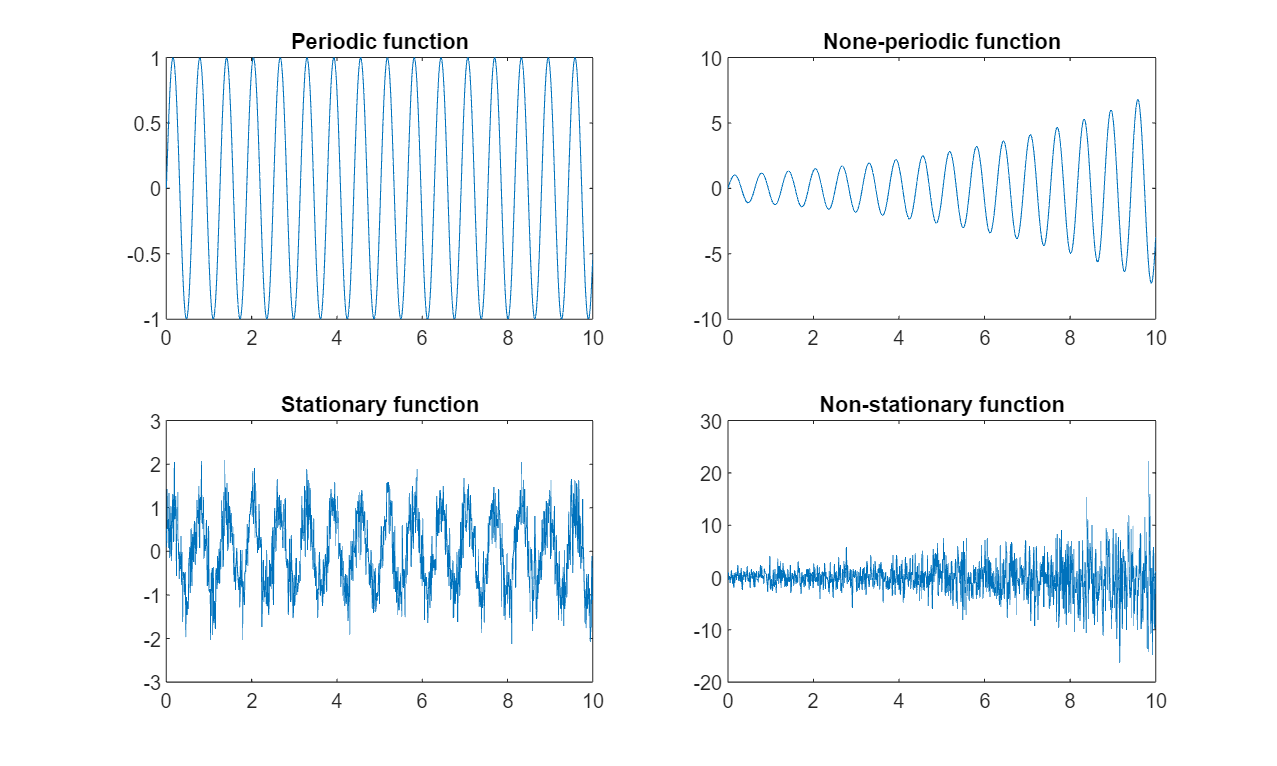

srate = 100;
time  = 0:1/srate:10;

periodic = sin(10*time);
nonperiodic = exp(0.2*time).*sin(10*time);
stationary = sin(10*time) + 0.5*randn(size(time));
nonstationary = exp(0.2*time).*randn(size(time));

figure('Position',[100,100,1000,600])

subplot(2,2,1)
plot(time,periodic)
title('Periodic function')

subplot(2,2,2)
plot(time,nonperiodic)
title('None-periodic function')

subplot(2,2,3)
plot(time,stationary)
title('Stationary function')

subplot(2,2,4)
plot(time,nonstationary)
title('Non-stationary function')

**Figure 11.4**

*A periodic signal is shown as *$f\left(t\right)=\sin \left(10\;t\right)$*, a non-periodic signal as *$f\left(t\right)=e^{0\ldotp 2\;t} \sin \left(10\;t\right)$*, a stationary random signal as *$f\left(t\right)=\sin \left(10\;t\right)+\varepsilon$*, and a non-stationary random signal as *$f\left(t\right)=e^{0\ldotp 2\;t} \varepsilon$*.*

**Fourier Theorem:** Any periodic signal is composed of a superposition of pure sine waves, with suitably chosen amplitudes and phases, whose frequencies are harmonics of the fundamental frequency of the signal.

### 12.2.1 Fourier Series

We can express any periodic function of time as sums of sine and cosine functions. For an arbitrary periodic function ($T$ is the period of the function), we can write it down as the sum of a symmetric and an antisymmetric part:

### 
$$x\left(t\right)=\frac{a_0 }{2}+\sum_{n=1}^{\infty } a_n \;\cos \left(n2\pi f_0 t\right)+\sum_{n=1}^{\infty } b_n \;\sin \left(n2f_0 t\right)$$


- $x\left(t\right)$ is the periodic function.

- $a_0$, $a_n$�, and $b_n$� are the Fourier coefficients, which are constants determined by the specific function.

- $f_o$ is the fundamental frequency of the function. It represents the lowest positive frequency component present in the function.

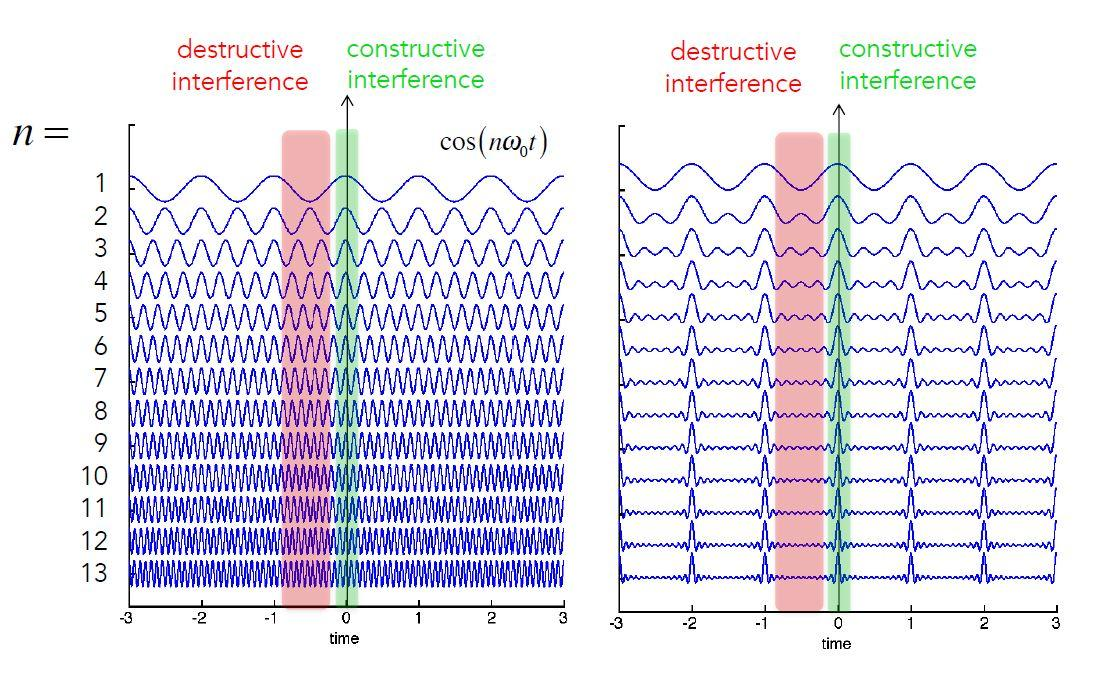

**Figure 11.5**

Demonstration of creating a periodic function with a sum of cosines.

How do we find the coefficients? The $a_0$ coefficient is just like the average of our function $x\left(t\right):$

### 
$$a_0 =\frac{2}{T}\int_{T/2}^{T/2} x\left(t\right)dt$$


The $a_n$ coefficient is just the overlap of our function $x\left(t\right)$ with $\cos \left(n2\pi f_0 t\right)$:

### 
$$a_n =\frac{2}{T}\int_{-T/2}^{T/2} x\left(t\right)\;\cos \left(n2\pi f_0 t\right)\;dt$$


The $b_n$ coefficient is just the overlap of our function $x\left(t\right)$ with $\sin \left(n2\pi f_0 t\right)$:

### 
$$b_n =\frac{2}{T}\int_{-T/2}^{T/2} x\left(t\right)\;\sin \left(n2\pi f_0 t\right)\;dt$$


### 12.2.2 Complex Fourier Series

We can express any periodic function of time as sums of complex exponentials.

In $x\left(t\right)=\frac{a_0 }{2}+\sum_{n=1}^{\infty } a_n \;\cos \left(n2\pi f_0 t\right)+\sum_{n=1}^{\infty } b_n \;\sin \left(n2f_0 t\right)$:

- The term $\frac{a_0 }{2}+\sum_{n=1}^{\infty } a_n \;\cos \left(n2\pi f_0 t\right)$ is symmetric

- The term $\sum_{n=1}^{\infty } b_n \;\sin \left(n2f_0 t\right)$ is antisymmetric

We can replace the sine and cosines of the fourier series with a single sum of complex exponentials:

### 
$$x\left(t\right)=\sum_{n=-\infty }^{\infty } X_n \;e^{i\;n\;2\pi \;f_{0\;} t}$$


- $X_n \;$the Fourier coefficient for the $n$-th harmonic

- $i$ is imaginary, where $i^2 =-1$

Again how do we find the coefficients? The $X_n$ coefficient is just the overlap of our function $x\left(t\right)$ with $e^{i\;n\;2\pi \;f_{0\;} t}$:

### 
$$X_n =\frac{1}{T}\int_{-T/2}^{T/2} x\left(t\right)\;e^{-i\;n\;2\pi \;f_{0\;} t} \;dt$$


### 12.2.3 Fourier transform

The Fourier transform is applicable for non periodic signals, while the Fourier series is applicable to periodic signals.

We are going to do this by letting the period go to infinity:

### 
$$T\longrightarrow \infty \;\;\;\;\;\;\;\;\;\;,\;\;\;\;\;\;\;\;\;2\pi \;f_0 \longrightarrow 0\;\;\;\;\;\;\;\;\;\;,\;\;\;\;\;\;\;\;\;n{\;f}_0 =f\;\;\;\;\;\;\;\;\;\;,\;\;\;\;\;\;\;\;\;X_n \longrightarrow X_f$$


them, for Fourier Transform we can write:

### 
$$X_f =\int_{-\infty }^{\infty } x\left(t\right)\;e^{-i\;n\;2\pi \;f\;t} \;dt$$


The mathematical formulas for Fourier Transforms can be quite dense and challenging to grasp intuitively. That’s why the best way to learn how the Fourier Transform works is by programming the discrete time Fourier Transform.

## 11.3 The Discrete Time Fourier Transform

The idea behind the discrete time Fourier transform is fairly simple: 

- Create a sine wave

- Compute the dot product between that sine wave and the time series data

- Then create another sine wave with a different frequency

- Compute the dot product between that sine wave and the same time series data

- ...

The number of sine waves you create, and the frequency of each sine wave, is determined by the number of data points in the time series data. The following Matlab code will perform a discrete time Fourier transform of random data:

There are two steps that occur within each iteration of this for-loop: 

- A sine wave is created. The frequency of that sine wave is defined by the looping index, and the looping index in turn is defined by the number of points in the data (in this case, the variable $N$). The equation for the sine wave is a complex sine wave. The sine wave at each iteration corresponds to a frequency one step slower than that iteration. Thus, the first iteration of this loop produces a sine wave with zero frequency, known as the "DC component".

- Dot product between the sine wave and the data is computed. Indeed, the Fourier transform works by computing the dot product between the signal and sine waves of different frequencies.

To convert the frequencies to hertz, consider that the number of unique frequencies that can be extracted from a time series is exactly one-half of the number of data points in the time series, plus the zero frequency. This is due to the Nyquist theorem. Thus, the number of unique frequencies that can be extracted from a time series of length $N$ is $N/2+1$ (the $+1$ is for the zero frequency component). This also means that $N/2+1$ is the frequency resolution of the data. Because frequencies start at zero and go up to the Nyquist frequency, to convert frequencies from indices to hertz, you create linearly equally spaced numbers between zero and the Nyquist frequency in $N/2+1$ steps. This can be done in Matlab using the function `linspace`;

For completeness, below is the formula for the discrete Fourier transform of variable $x$ at frequency $f$.

### 
$$X_f =\sum_{k=1}^n x_k \;e^{-i\;2\pi \;f\;\left(k-1\right){\;n}^{-1} }$$


- $n$ is the number of data points in vector $x$

- $X_f$ is the Fourier coefficient of time series variable $x$ at frequency $f$

## 11.4 Visualizing the Results of a Fourier Transform

Remember that the Fourier transform provides a 3-D representation of the data in terms of frequency, power, and phase. Very often, the phase information is ignored when results of a Fourier analysis are shown, thus leaving two dimensions to show.

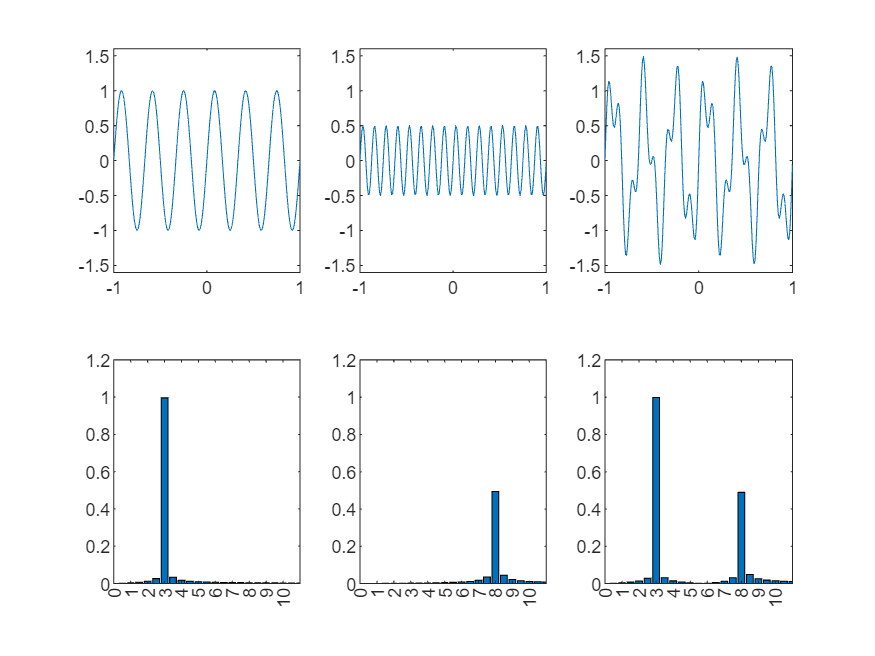

time=-1:1/srate:1;

s1 = sin(2*pi*3*time);
s2 = 0.5*sin(2*pi*8*time);
s3 = s1+s2;

figure
for i=1:3
    subplot(2,3,i)
    
    eval([ 'plot(time,s' num2str(i) ')' ]);
    set(gca,'ylim',[-1.6 1.6],'ytick',-1.5:.5:1.5)
    
    subplot(2,3,i+3)
    f  = eval([ 'fft(s' num2str(i) ')/length(time)' ]);
    hz = linspace(0,srate/2,floor(length(time)/2)+1);
    bar(hz,abs(f(1:length(hz))*2))
    set(gca,'xlim',[0 11],'xtick',0:10,'ylim',[0 1.2])
end

**Figure 11.6**

*Two sine waves of 3 Hz and 8 Hz, and their sum have a Fourier power spectrum that can be represented in plots of frequency ( x- axis) by amplitude ( y -axis).*

As mentioned earlier, although the result of a Fourier transform is often presented in 2-D plots for convenience, the result of a Fourier transform actually occupies a 3-D space.

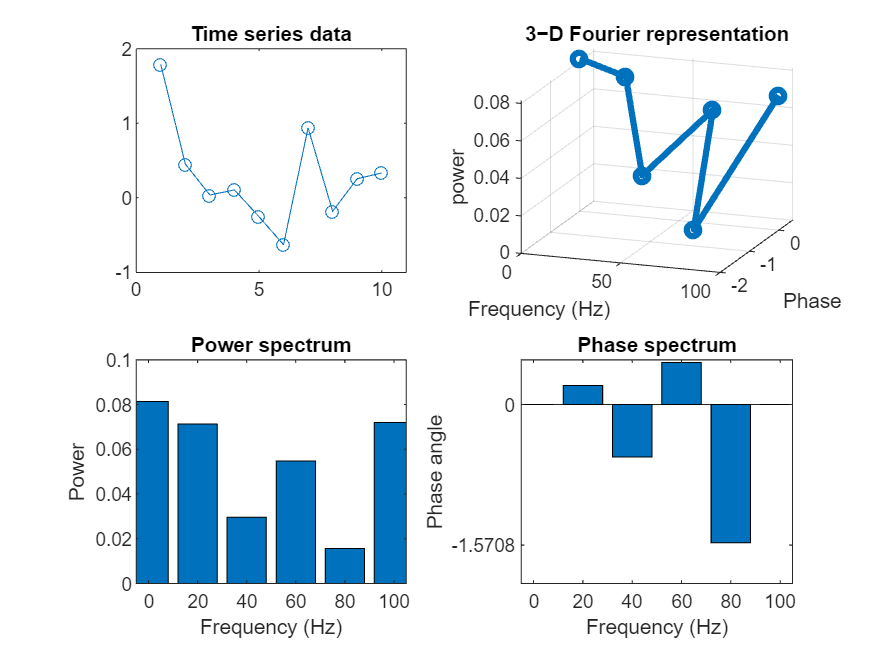

N       = 10;
data    = randn(1,N);
srate   = 200;
nyquist = srate/2;


fourier = zeros(size(data)); 

frequencies = linspace(0,nyquist,N/2+1);
time = ((1:N)-1)/N;

for fi=1:N
    sine_wave   = exp(-1i*2*pi*(fi-1).*time);
    fourier(fi) = sum(sine_wave.*data);
end
fourier=fourier/N;

figure
subplot(221)
plot(data,'-o')
set(gca,'xlim',[0 N+1])
title('Time series data')

subplot(222)
plot3(frequencies,angle(fourier(1:N/2+1)),abs(fourier(1:N/2+1)).^2,'-o','linew',3)
grid on
xlabel('Frequency (Hz)')
ylabel('Phase')
zlabel('power')
title('3−D Fourier representation')
view([20 20])

subplot(223)
bar(frequencies,abs(fourier(1:N/2+1)).^2)
set(gca,'xlim',[-5 105])
xlabel('Frequency (Hz)')
ylabel('Power')
title('Power spectrum')

subplot(224)
bar(frequencies,angle(fourier(1:N/2+1)))
set(gca,'xlim',[-5 105])
xlabel('Frequency (Hz)')
ylabel('Phase angle')
set(gca,'ytick',-pi:pi/2:pi)
title('Phase spectrum')

**Figure 11.7**

3-D representation of Fourier transform.

## 11.5 Complex Results and Negative Frequencies

`fourier` has the form $a+\mathrm{ib}$. This is the representation of a complex number and is crucial for extracting power and phase information. For now, you can just plot `abs(fourier)` in Matlab, which gives you the amplitude of the Fourier series.

The first half of the Fourier series contains the “positive” frequencies, and the second half of the Fourier series contains the “negative” frequencies. The negative frequencies capture sine waves that travel in reverse order around the complex plane compared to those that travel forward (positive frequencies). This feature of the Fourier transform will become relevant when you learn about the Hilbert transform. For a signal with only real numbers (as is the case with EEG data), the negative frequencies mirror the positive frequencies; you can thus ignore the negative frequencies and double the amplitudes of the positive frequencies. However, do not remove the negative frequencies from the Fourier series because you will need them to compute the inverse Fourier transform.

## 11.6 Inverse Fourier Transform

It is often stated that the Fourier transform is a perfect frequency-domain representation of a time-domain signal. If this is true, it must be possible to reconstruct the original time series data with only the frequency domain information. This is done through the inverse Fourier transform.

To compute the inverse Fourier transform, you build sine waves of specific frequencies, multiply them by the respective Fourier coefficients at those frequencies, sum all of these sine waves together, and then divide by the number of sine waves (which is also the number of points in the time series). This will result in a perfect reconstruction of the original time series data.

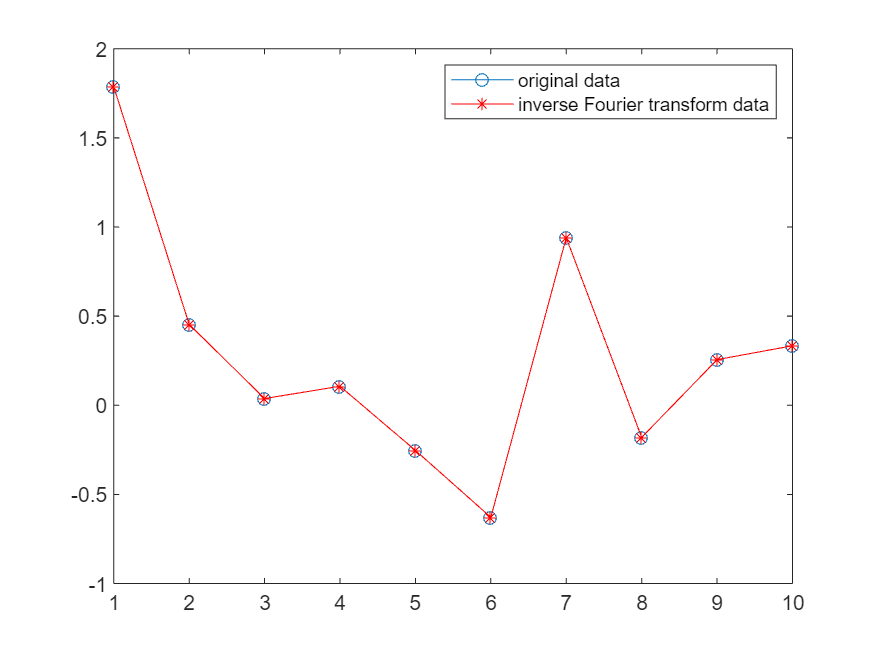

reconstructed_data = zeros(size(data));
for fi=1:N
    sine_wave = fourier(fi)*exp(1i*2*pi*(fi-1).*time);
    reconstructed_data = reconstructed_data + real(sine_wave);
end

figure
plot(data,'-o')
hold on
plot(reconstructed_data,'r-*')
legend({'original data';'inverse Fourier transform data'})

**Figure 11.8**

*Time series data of randomly generated numbers and the reconstruction of the data using the inverse discrete time Fourier transform (IDTFT).*

For completeness, bellow equation shows the formula for the inverse Fourier transform.

### 
$$x_k =\sum_{k=1}^n X_k \;e^{i\;2\pi \;f\;\left(k-1\right){\;n}^{-1} }$$


Notice that, the dot product (here, a single multiplication) is computed between the complex sine wave and the Fourier coefficients $X$ instead of the time series data $x$. Also the exponential contained a negative sine in formula for the Fourier transform, which is absent in formula for the inverse Fourier transform.

For the statistically oriented readers, there is also a statistical explanation of why the Fourier transform can perfectly represent a time series. If the time series is modeled using the same number of sine waves (analogous to regressors) as data points, there are no remaining degrees of freedom, and thus, the model must explain 100% of the variance of the data.

## 11.7 The Fast Fourier Transform

There is a much faster, more efficient, and more elegant way to compute the Fourier transform. It turns out that if you break up the Fourier transform into all of its individual multiplication and addition steps, many of these individual elements are redundant and can be eliminated, thus allowing the Fourier transform to be computed much faster and with no loss of information. There are several methods for increasing the efficiency of the Fourier transform, including the fast Fourier transform (FFT) that is implemented in Matlab using the function `fft`. The Matlab function for the inverse Fourier transform is called `ifft`.

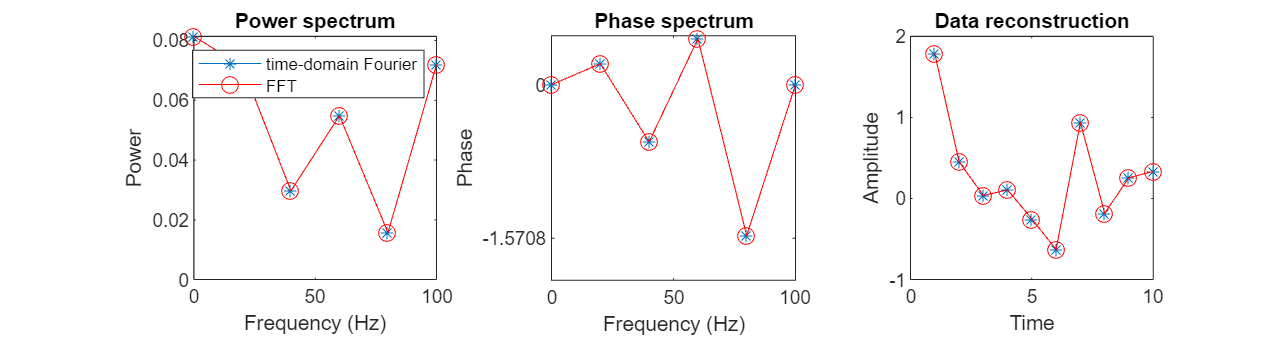

fft_data = fft(data)/N;

figure('Position', [100 100 1500 400])
subplot(131)
plot(frequencies,abs(fourier(1:N/2+1)).^2,'*-')
hold on
plot(frequencies,abs(fft_data(1:N/2+1)).^2,'ro-','markersize',8)
xlabel('Frequency (Hz)')
ylabel('Power')
title('Power spectrum')
axis square
legend({'time-domain Fourier';'FFT'})

subplot(132)
plot(frequencies,angle(fourier(1:N/2+1)),'*-')
hold on
plot(frequencies,angle(fft_data(1:N/2+1)),'ro-','markersize',8)
xlabel('Frequency (Hz)')
ylabel('Phase')
set(gca,'ytick',-pi:pi/2:pi)
title('Phase spectrum')
axis square

subplot(133)
plot(reconstructed_data,'*-')
hold on
plot(ifft(fft(data)),'ro-','markersize',8)
xlabel('Time')
ylabel('Amplitude')
title('Data reconstruction')
axis square

**Figure 11.9**

*The fast Fourier transform (FFT) produces identical results as the discrete time Fourier transform and is much faster.*

The FFT is significantly faster than a discrete time Fourier transform computation. This speed advantage grows with data size: the more data points ($N$), the greater the performance increase.

- The discrete time Fourier transform's computation scales as $O\left(N^2 \right)$, while the FFT’s scales as $O\left(\textrm{NlogN}\right)$. This fundamental difference means the FFT becomes vastly more efficient as $N$ increases.

- The FFT is particularly optimized for data lengths that are powers of two ($N=2^k$). When data length is a power of two, the FFT’s performance gain over the discrete time Fourier transform can be dramatic, sometimes reaching 3 orders of magnitude (e.g., millions of points taking minutes instead of hours).

In essence, the FFT leverages a more efficient algorithm and benefits from data structured as powers of two, making it the standard for analyzing large datasets.

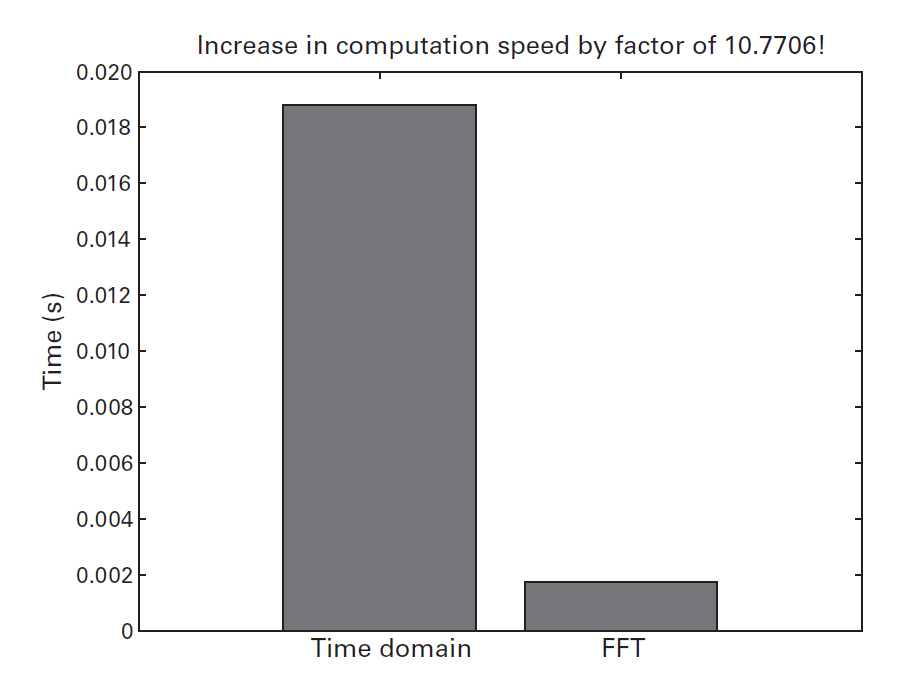

**Figure 11.10**

*Computation times for the discrete time Fourier transform versus the FFT with *640 time points of data*.*

## 11.8 Stationarity and the Fourier Transform

One assumption of the Fourier transform is that your data are stationary, which means that the statistics of the data, including the mean, variance, and frequency structure, do not change over time. This is clearly not the case for EEG data: the frequency structure of neurophysiological activity changes over time both because of task events and because of endogenous processes.

Violations of stationarity can decrease the peakiness of the results of the Fourier transform. the nonstationary time series has a more complicated structure and therefore requires energy at a larger number of frequencies in order to represent the time series in the frequency domain.

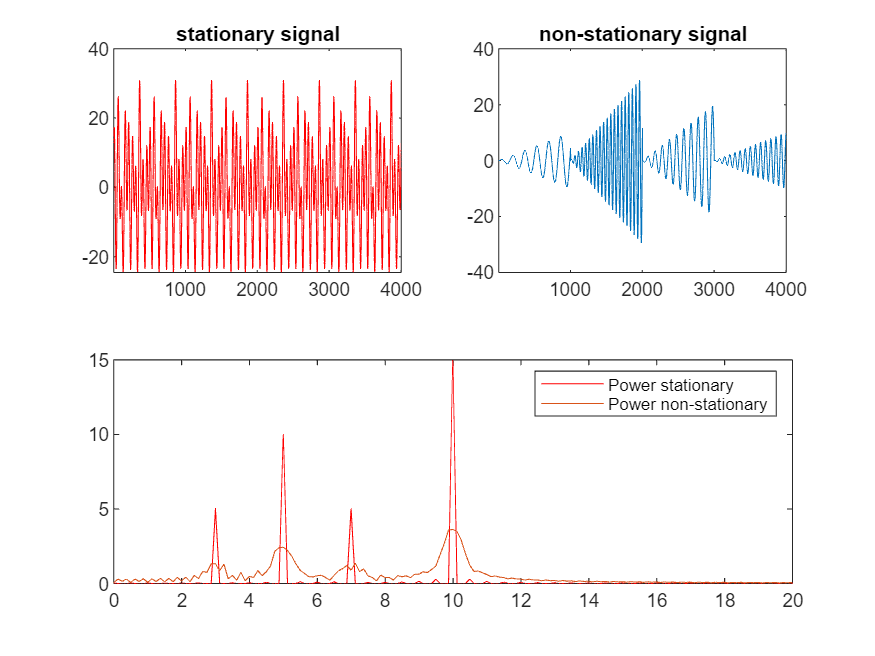

frex = [ 3 10 5 7 ];
amplit = [ 5 15 10 5 ];
phases = [  pi/7  pi/8  pi  pi/2 ];

srate = 500;
time = -1:1/srate:1;
stationary  = zeros(1,length(time)*length(frex));
nonstationary = zeros(1,length(time)*length(frex));

for fi=1:length(frex)
    
    temp_sine_wave = amplit(fi) * sin(2*pi*frex(fi).*time + phases(fi));
    stationary = stationary + repmat(temp_sine_wave,1,length(frex));
    
    temp_sine_wave = temp_sine_wave.*(time+1);
    start_idx = (fi-1)*length(time)+1;
    stop_idx  = (fi-1)*length(time)+length(time);
    nonstationary(start_idx:stop_idx) = temp_sine_wave;

end

figure

subplot(221)
plot(stationary,'r')
set(gca,'xlim',[1 length(stationary)])
title('stationary signal')

subplot(222)
plot(nonstationary)
set(gca,'xlim',[1 length(nonstationary)])
title('non-stationary signal')

frequencies       = linspace(0,srate/2,length(nonstationary)/2+1);
fft_nonstationary = fft(nonstationary)/length(nonstationary);
fft_stationary    = fft(stationary)/length(stationary);
subplot(212)
plot(frequencies,abs(fft_stationary(1:length(frequencies)))*2,'r')
hold on
plot(frequencies,abs(fft_nonstationary(1:length(frequencies)))*2)
set(gca,'xlim',[0 max(frex)*2])
legend({'Power stationary';'Power non-stationary'})

**Figure 11.11**

Violations of stationarity (here introduced by changes in frequency and amplitude over time) result in energy at frequencies that were not explicitly generated when creating the data. 

There are two main reasons to perform temporally localized frequency decomposition methods such as wavelet convolution, filter-Hilbert, or short-time FFT:

- With temporally localized methods, you assume that the data are stationary within relatively brief periods of time, which seems to be a reasonable assumption for EEG data.

- The Fourier transform does not show how dynamics change over time. That is, although the Fourier transform contains all temporal information of the time series data,as demonstrated by the ability of the inverse Fourier transform to reconstruct a time series, time-varying changes in the frequency structure cannot be observed directly in power or phase plots.

## 11.9 Extracting More or Fewer Frequencies than Data Points

It is possible to get more or fewer frequencies from a Fourier transform. Because the number of frequencies is related to the number of data points, you can simply add data points to get more frequencies. However, because you may not have more real data to add, you can add zeros after the end of the time series. This is called zero padding. Zero padding increases the N of the Fourier transform without changing the data, thus allowing you to get more frequencies from the Fourier transform. However, because zero padding does not increase the amount of information in the data, it does not increase the frequency precision of the Fourier transform, only the frequency resolution.

The Matlab function `fft` has an optional second input, which is the order of the FFT ($N$), which determines the number of frequencies that are extracted. By default, $N$ is equal to the number of data points, but you can specify this number to be larger or smaller. If $N$ is larger than the number of data points, the time series will be zero-padded, and the FFT will return more frequencies. Conversely, if $N$ is smaller than the number of data points, data points will be removed from the end of the time series. Although zero padding does not provide any additional information, it can make frequency-domain convolution more convenient and faster to perform. 

## 11.10 The Convolution Theorem

Convolution theorem states that convolution in the time domain is the same as multiplication in the frequency domain. (The opposite is also true) Thus, you can perform convolution in two ways: 

- Time-domain convolution: by flipping the kernel backward, sliding it along the signal, and computing the dot product at each time step. 

- Frequency-domain convolution: by taking the Fourier transforms of the signal and the kernel, multiplying the Fourier transforms together point-by-point, and then taking the inverse Fourier transform. 

Time-domain convolution is slow, and frequency-domain convolution is fast.

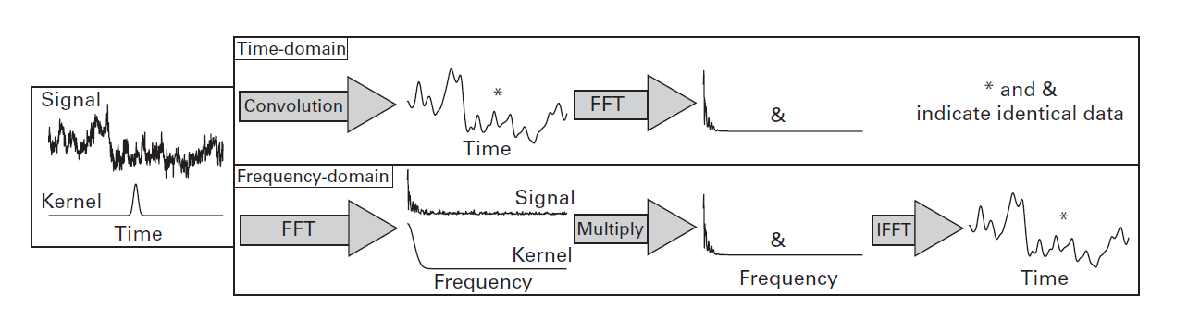

**Figure 11.12**

*Illustration of the convolution theorem and the interchangeability of time-domain convolution and frequency-domain multiplication.*

When you perform the frequency-by-frequency multiplication of the Fourier transforms of the kernel and the signal, you are scaling the frequency spectrum of the signal by the frequency spectrum of the kernel. In other words, the result of the multiplication (and hence, the result of the convolution) is the frequency structure that is common to both the kernel and the signal. This is why convolution can be conceptualized as a frequency-domain filter. Thus, convolution acts as a filter such that the frequency profile of the signal is passed through the frequency profile of the kernel.

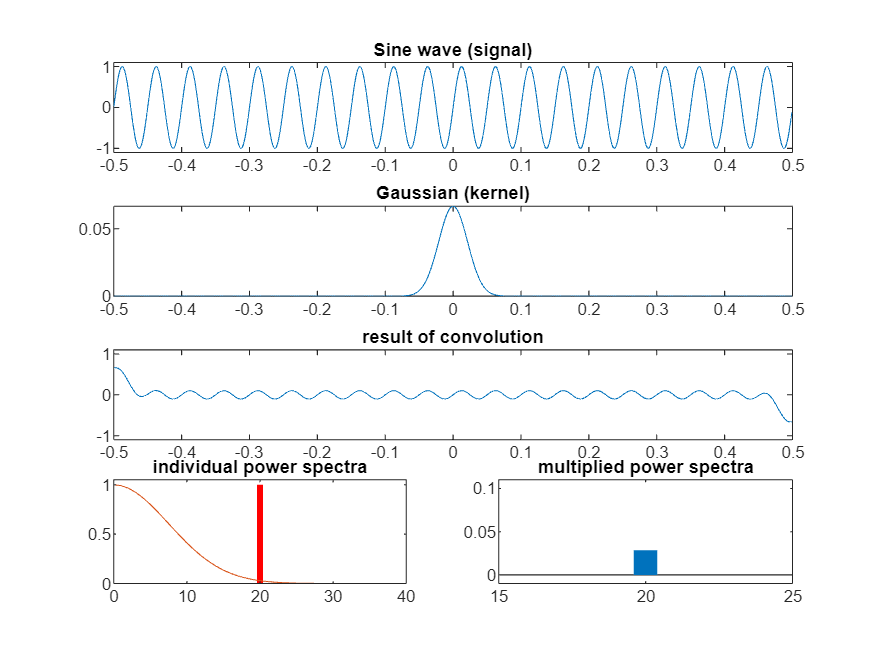

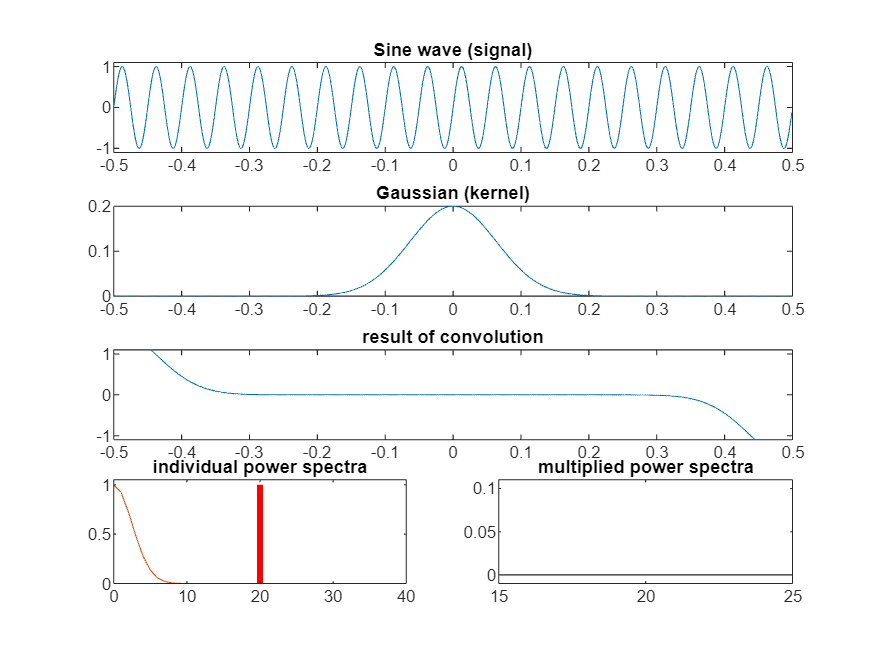

srate = 1000;
time  = -.5:1/srate:.5-1/srate;
f     = 20;
fg    = [15 5];
s     = sin(2*pi*f*time);

for i=1:2
    
    g = exp((-time.^2)/(2*(4/(2*pi*fg(i))^2)))/fg(i);
    
    figure
    
    subplot(411)
    plot(time,s)
    title('Sine wave (signal)')
    set(gca,'ylim',[-1.1 1.1])
    
    subplot(412)
    plot(time,g)
    title('Gaussian (kernel)')
    
    subplot(413)
    plot(time,conv(s,g,'same'))
    set(gca,'ylim',[-1.1 1.1])
    title('result of convolution')
    
    subplot(427)
    fft_s = abs(fft(s));
    fft_s = fft_s(1:floor(length(fft_s)/2)+1)./max(fft_s(1:floor(length(fft_s)/2)+1));
    bar(0:500,fft_s,'r')
    hold on
    
    fft_g = abs(fft(g));
    fft_g = fft_g(1:floor(length(fft_g)/2)+1)./max(fft_g(1:floor(length(fft_g)/2)+1));
    plot(0:500,fft_g)
    set(gca,'xlim',[0 40],'ylim',[0 1.05])
    title('individual power spectra')
    
    subplot(428)
    bar(0:500,fft_g.*fft_s)
    set(gca,'xlim',[0 40],'ylim',[0 .035])
    title('multiplied power spectra')

    axis([15 25 -.01 .11])
end

**Figure 11.13**

*The convolution between a 20-Hz sine wave and a narrow Gaussian dampens the sine wave, whereas the convolution between the same sine wave and a wide Gaussian obliterates the sine wave.*

The result of convolving the EEG data with a Gaussian is a time series comprising the frequency characteristics of the EEG data weighted by the frequency characteristics of the Gaussian. Thus, the Gaussian kernel is a low-pass filter because its spectral characteristics are dominated by low frequencies, and thus, the high frequencies of the EEG data are severely attenuated.

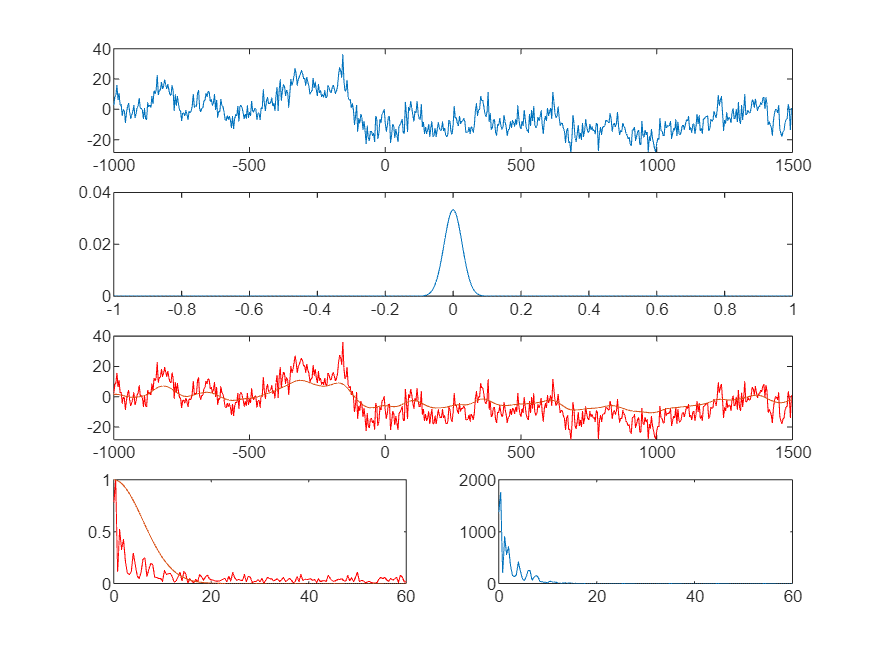

load sampleEEGdata
eegdat4convol = squeeze(EEG.data(47,:,1));

time = -1:1/EEG.srate:1;
s = 5/(2*pi*30);
gaussian = exp((-time.^2)/(2*s^2))/30;

figure

subplot(411)
plot(EEG.times,eegdat4convol)

subplot(412)
plot(time,gaussian)

subplot(413)
plot(EEG.times,eegdat4convol,'r')
hold on
plot(EEG.times,conv(eegdat4convol,gaussian,'same'))

subplot(427)
nfft = length(eegdat4convol);
fft_s = abs(fft(eegdat4convol,nfft));
fft_s = fft_s(1:floor(nfft/2)+1);
f = linspace(0,EEG.srate/2,floor(nfft/2)+1);
plot(f,fft_s./max(fft_s),'r')
hold on

fft_g = abs(fft(gaussian,nfft));
fft_g = fft_g(1:floor(nfft/2)+1);
plot(f,fft_g./max(fft_g))

set(gca,'xlim',[0 60])

subplot(428)
plot(f,fft_s.*fft_g)
set(gca,'xlim',[0 60])

**Figure 11.15**

*Convolving an EEG time series from one trial with a Gaussian low-pass-filters the data.*

## 11.11 Tips for Performing FFT-Based Convolution in Matlab

If you try to perform FFT-based convolution by taking the inverse Fourier transform of the products of the Fourier transforms of the EEG data and the wavelet (or any signal and kernel), you will get an incorrect result. In fact, you may get a Matlab error if the signal and the kernel are not the same length. Even if the signal and the kernel are the same length, the following Matlab command will not produce a valid convolution:

The reason the above line of code will not produce a valid convolution is that the result of convolution must be equal to the length of the signal plus the length of the kernel minus one. Thus, you will need to make the inverse FFT return the correct number of time points, and to do this, you will need to make sure to compute the FFTs of the signal and the kernel using the appropriate number of time points (in other words, the length of the signal plus the length of the kernel minus one). Remember that the result of the FFT can be greater than the number of time points in the input if the fft function is called with a second argument that specifies the desired number of frequency points. After you compute the inverse Fourier transform, you will then need to remove the appropriate number of time points from the beginning and from the end of the time series. This is the correct way to perform a convolution using the fft and ifft functions.

This is a tricky point, and it is very important. If you do not use the fft function appropriately, you will get a result (if the signal and the kernel have the same number of time points), but that result will not be a convolution! You can easily double-check your code to make sure you ’ ve done it correctly by using the Matlab conv function:

This result should be identical to the result of the FFT-based convolution. If you use the ‘ full ’ option instead of the ‘ same ’ option, the result will the length of the result of convolution, that is, the length of the signal plus the length of the kernel minus one. In theory, you can always use the conv function instead of performing convolution using fft and ifft . However, using the conv function is inefficient for wavelet convolution with many frequencies because you will redundantly recompute the FFT many times. This can slow data analysis times by an order of magnitude or more.